# Check Small Martini Runs

Using the Gromacs 5 Suite, we have run NPT systems of 50 and 100 molecules at number concentrations of 100/(18.652^3) nm^-3 (concentrations of 30 mM) at 298 K and 1 bar (same as in previous papers, except for Gromacs 5).

Now we check their optical and contact cluster sizes, and then the fractal dimension on different length scales to begin with.  

Alternative possibilities for objective functions include "alignment" from Bryce's 2018 paper (but this is relatively similar to the optical/contact cluster stuff and maybe more difficult to measure across the whole simulation?), or distribution of angles as in the 2017 Flow/pH paper (although I don't know that this is any *better*?)

basefolder = '/Users/Messiah/Eostre/';

## Optical versus Contact Cluster Sizes

Reminder


$$\mu_2 = \frac{\sum_{i=1}^N i^2N_i}{\sum_{i=1}^N i N_i$$


and if we have the ID of each cluster then 

Undefined function or variable 'mols'.


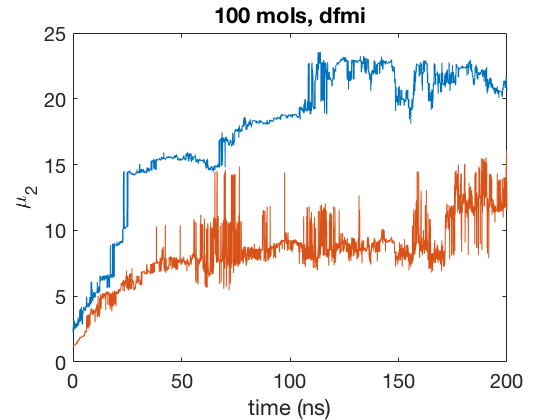

chems = {'dfmi','dmfi','dggg','dgag','dgga'};
savefolder = '/Users/Messiah/Desktop/';
for c = 1:length(chems)
    chem = chems{c};
fnames = {[basefolder 'coarsegraining/CG/active_learning/martini-assembly/' chem '/4_production/'],[basefolder 'coarsegraining/CG/active_learning/martini-assembly/small-box1/' chem '/4_production/']};
for f = 1:length(fnames)
    fname = fnames{f};
osizedata = importdata([fname 'optical-sizes.dat']);
csizedata = importdata([fname 'contact-sizes.dat']);
tsteps = size(osizedata,1);
nmols = size(osizedata,2);
tconv = 20; %20 ns/frame
ts = (0:3999)/tconv;
omu2 = zeros(tsteps,1);
for t = 1:tsteps
    currsize = osizedata(t,:);
    currm2 = 0;
    currm1 = 0;
    for i = 1:max(currsize)
        currm1 = currm1 + sum(currsize==i);
        currm2 = currm2 + sum(currsize==i)*i;
    end
    omu2(t) = currm2/currm1;
end

cmu2 = zeros(tsteps,1);
for t = 1:tsteps
    currsize = csizedata(t,:);
    currm2 = 0;
    currm1 = 0;
    for i = 1:max(currsize)
        currm1 = currm1 + sum(currsize==i);
        currm2 = currm2 + sum(currsize==i)*i;
    end
    cmu2(t) = currm2/currm1;
end
figure()
plot(ts,cmu2)
hold on
set(gca,'fontsize',20)
plot(ts,omu2)
xlabel('time (ns)')
ylabel('\mu_2')
title([int2str(nmols) ' mols, ' chem])
saveas(gcf,[savefolder chem int2str(nmols) 'mols'],'png')
end
end